# Clase 12-1

Importar Alexnet y listar las imágenes de la carpeta `originales`

red = alexnet;
ls originales\*.jpg


file_01.jpg  file_03.jpg  file_05.jpg  file_07.jpg  file_09.jpg  file_11.jpg  
file_02.jpg  file_04.jpg  file_06.jpg  file_08.jpg  file_10.jpg  file_12.jpg  



Crear un almacén de datos llamado que haga referencia a los archivos de imagen de la carpeta `originales`. Utilizar `montage` para mostrar todas las imágenes

ds_img = imageDatastore("originales\file_*.jpg")

ds_img =   ImageDatastore with properties:

                       Files: {
                              ' ...\Users\Pc\Documents\MATLAB\CLASS 16 DE 11 2022\originales\file_01.jpg';
                              ' ...\Users\Pc\Documents\MATLAB\CLASS 16 DE 11 2022\originales\file_02.jpg';
                              ' ...\Users\Pc\Documents\MATLAB\CLASS 16 DE 11 2022\originales\file_03.jpg'
                               ... and 9 more
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
                     ReadFcn: @readDatastoreImage


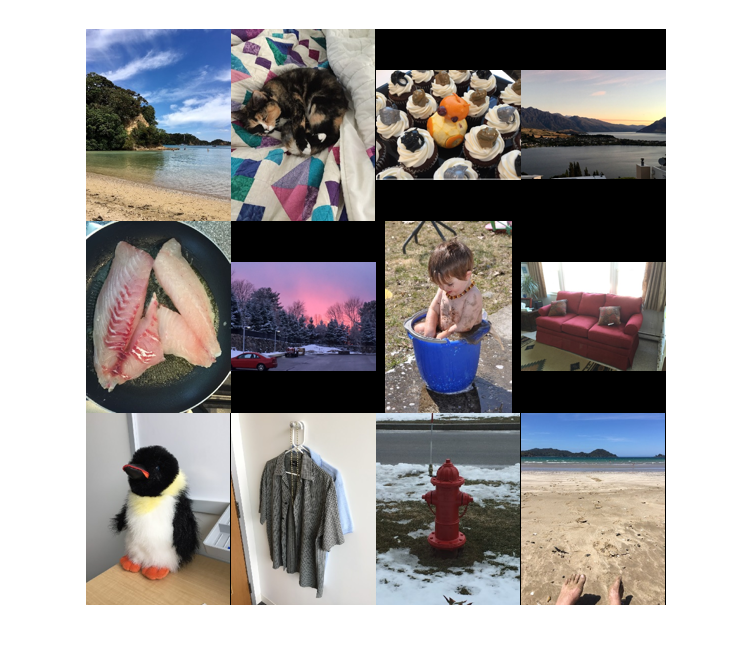

montage(ds_img)

Crear un almacén de datos de imágenes aumentadas que redimensione las imágenes a 227 por 227

ds_aum = augmentedImageDatastore([227 227],ds_img)

ds_aum =   augmentedImageDatastore with properties:

           MiniBatchSize: 128
         NumObservations: 12
        DataAugmentation: 'none'
      ColorPreprocessing: 'none'
              OutputSize: [227 227]
          OutputSizeMode: 'resize'
    DispatchInBackground: 0


Clasificar las imágenes de `ds_aum` mediante la función `classify`

pred = classify(red,ds_aum)

pred = 12×1 categorical array
     seashore 
     papillon 
     earthstar 
     lakeside 
     frying pan 
     traffic light 
     bucket 
     studio couch 
     Border collie 
     poncho 
     shovel 
     sandbar 
